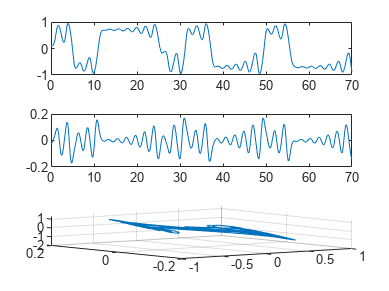

clear all
close all
clc

%% Parameters

a = 10;
b = 100/7;
r = 0;

tfin = 70;
u = 0;
x0 = 0.1*randn(3,1);

%% Implementation

%open("chuasim")
res = sim("chuasim");
time = res.chuaOut.Time;

data = res.chuaOut.Data;
figure(1)
plot3(data(:,1), data(:,2), data(:,3))
xlabel('X1')
ylabel('Y1')
zlabel('Z1')
hold on

figure(2)
tiledlayout(3,1);
nexttile;
plot(time, data(:,1))
nexttile;
plot(time, data(:,2))
nexttile;
plot(time, data(:,3))

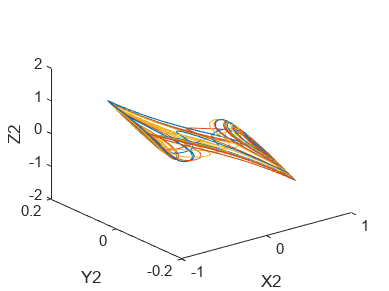


x0 = 0.00001*randn(3,1);
%open("chuasim")
res = sim("chuasim");

data = res.chuaOut.Data;
figure(1)
plot3(data(:,1), data(:,2), data(:,3))
xlabel('X2')
ylabel('Y2')
zlabel('Z2')
hold on

x0 = 0.001*randn(3,1);
%open("chuasim")
res = sim("chuasim");
data = res.chuaOut.Data;

plot3(data(:,1), data(:,2), data(:,3))
xlabel('X2')
ylabel('Y2')
zlabel('Z2')
hold on

## Equilibrium point


ep = [0,1/sqrt(2), -1/sqrt(2);0,0,0; 0,-1/sqrt(2),+1/sqrt(2) ]

ep =          0    0.7071   -0.7071
         0         0         0
         0   -0.7071    0.7071



syms x1 x2 x3 u1

p = 2* (x1^3/7) - 8*x1/7;
x = a * (x2 - x1 - p);
y = x1-x2 + x3 + u1;
z = -b*x2 - 0*x3;

A = jacobian([x,y,z],[x1,x2,x3]);
A1 = double(subs(A, [x1, x2, x2], ep(:,1)'))

A1 =     1.4286   10.0000         0
    1.0000   -1.0000    1.0000
         0  -14.2857         0


A2 = double(subs(A, [x1, x2, x2], ep(:,2)'));
A3 = double(subs(A, [x1, x2, x2], ep(:,3)'));

B = jacobian([x,y,z], u1);
B1 = double(subs(B, [u1],u));
B2 = double(subs(B, [u1], u));
B3 = double(subs(B, [u1], u));

eig1 = eig(A1)

eig1 =    2.5163 + 0.0000i
  -1.0439 + 2.6497i
  -1.0439 - 2.6497i


eig2 = eig(A2)

eig2 =   -4.3637 + 0.0000i
   0.2533 + 3.0478i
   0.2533 - 3.0478i


eig3 = eig(A3)

eig3 =   -4.3637 + 0.0000i
   0.2533 + 3.0478i
   0.2533 - 3.0478i



disp("The all 3 equilibrium point are unstable");

The all 3 equilibrium point are unstable


## Esercizio 3

x_0 = ep(:,1) + 0.01*randn(1,3)

x_0 =    -0.0133   -0.0144    0.0040
   -0.0133   -0.0144    0.0040
   -0.0133   -0.0144    0.0040


res = sim("chuasim");
time = res.chuaOut.Time;
data = res.chuaOut.Data;
figure(4)
plot3(data(:,1), data(:,2), data(:,3))
grid;




